clear; close all; clc

% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002=readmatrix('RUL_FD002.txt');
RUL_FD003=readmatrix('RUL_FD003.txt');
RUL_FD004=readmatrix('RUL_FD004.txt');

% Dataset 
trainSets = {trainFD001, trainFD002, trainFD003, trainFD004};
testSets  = {testFD001,  testFD002,  testFD003,  testFD004};
RULsets   = {RUL_FD001, RUL_FD002, RUL_FD003, RUL_FD004};
dataset_names = {'FD001','FD002','FD003','FD004'};

% Functions helper 
function T2 = t2comp(data, loadings, latent)
    k = size(loadings,2);
    scores = data*loadings;
    latent_rep = repmat(sqrt(latent(1:k))', size(scores,1),1);
    standscores = scores ./ latent_rep;
    T2 = sum(standscores.^2,2);
end

function Q = qcomp(data, loadings)
    k = size(loadings,2);
    scores = data*loadings;
    reconstructed = scores*loadings';
    residuals = data - reconstructed;
    Q = sum(residuals.^2,2);
end

function T2_contrib = t2contr(x_row, loadings, latent, k)
    score_row = x_row*loadings;
    T2_contrib = abs( (score_row ./ sqrt(latent(1:k))') ) * abs(loadings');
end

function Q_contrib = qcontr(x_row, loadings, k)
    reconstructed_row = (x_row*loadings)*loadings';
    residuals_row = x_row - reconstructed_row;
    Q_contrib = residuals_row.^2;
end


==================== Dataset: FD001 ====================


Removed 3 constant variables.


Split: 80 unit for training, 20 for validation.


Selected 12 PC to explain 91.0% of variance.


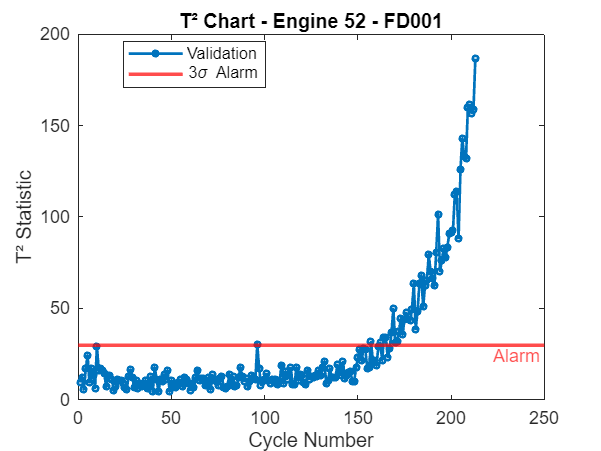

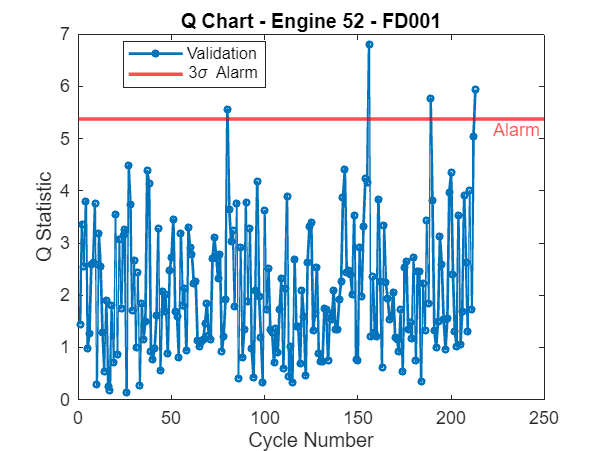

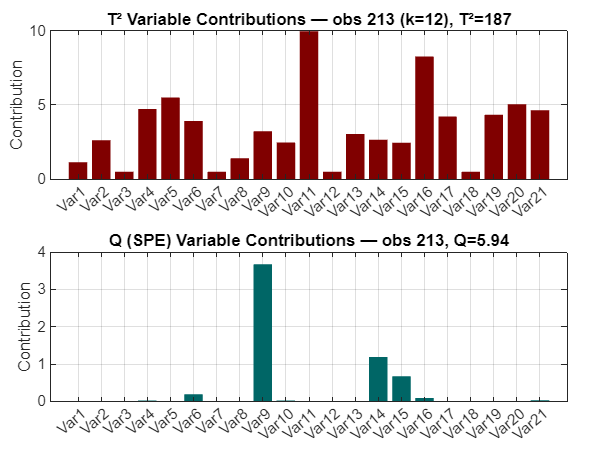

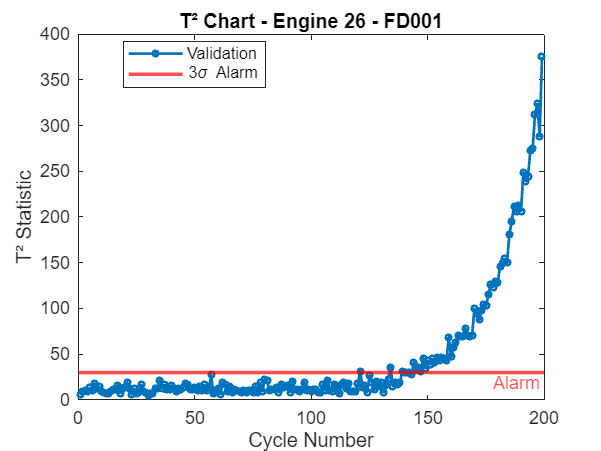

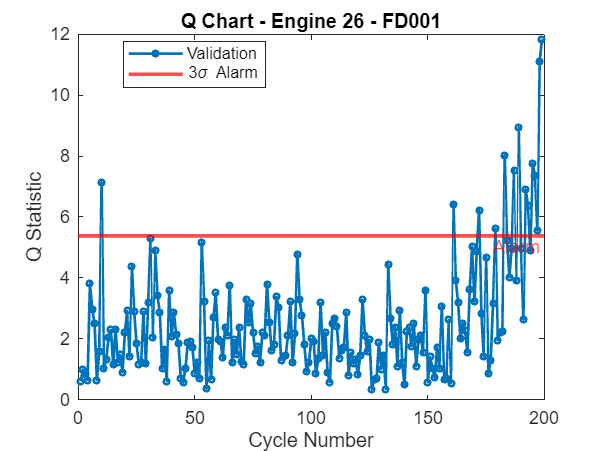

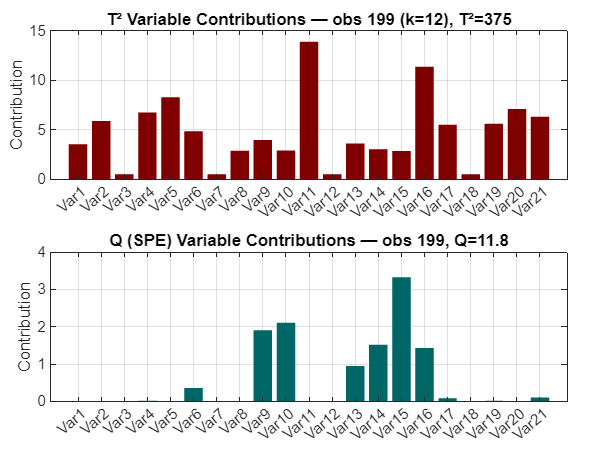

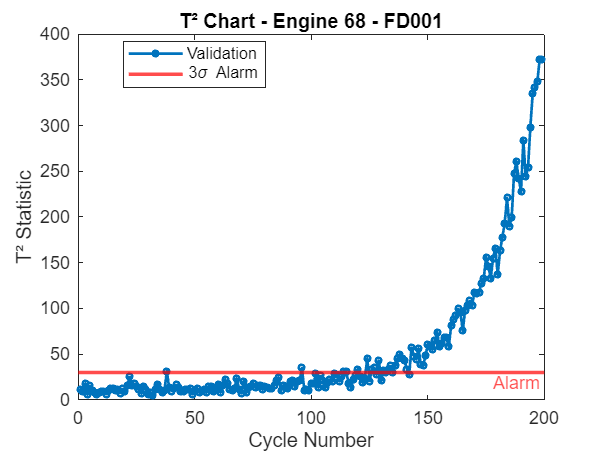

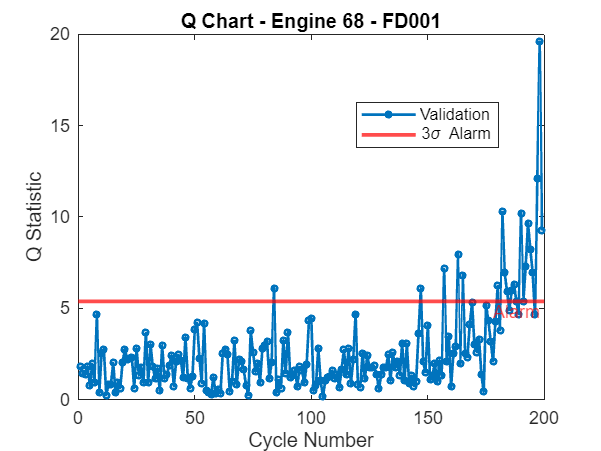


==================== Dataset: FD002 ====================


Split: 208 unit for training, 52 for validation.


Selected 2 PC to explain 97.4% of variance.


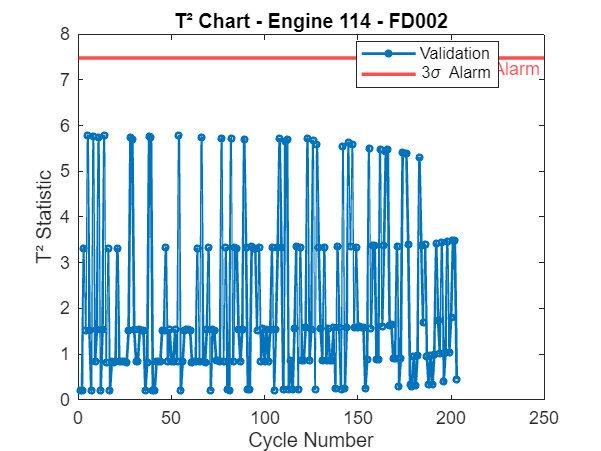

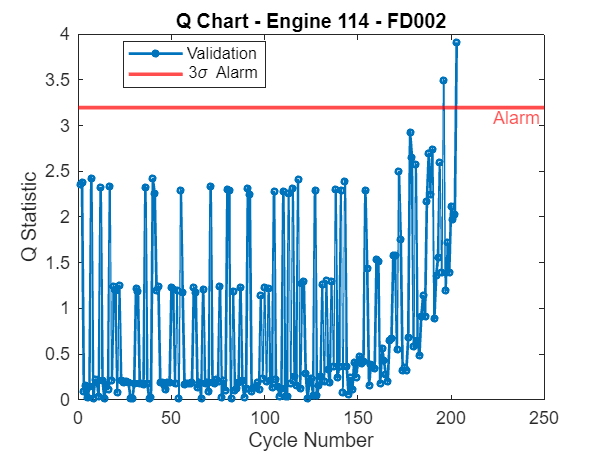

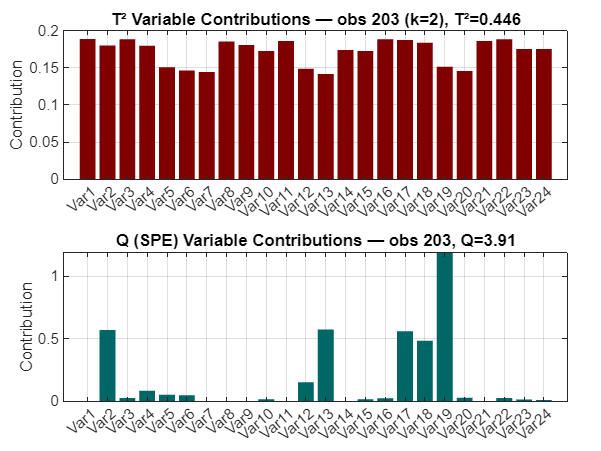

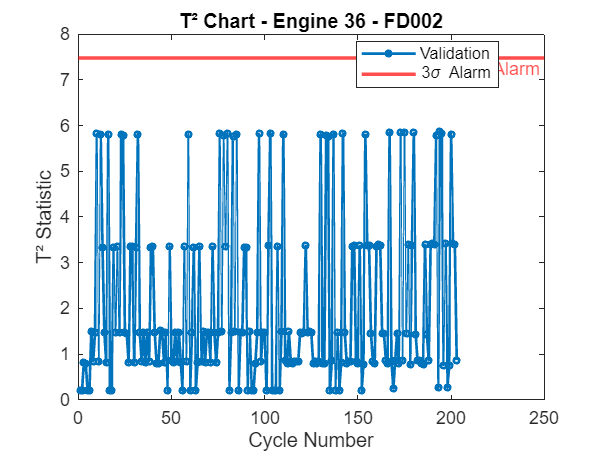

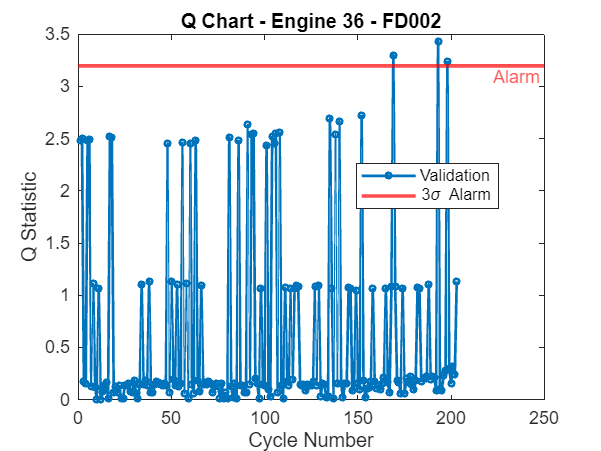

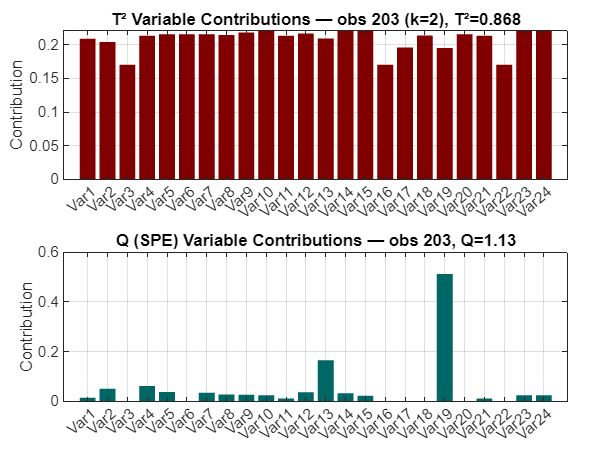

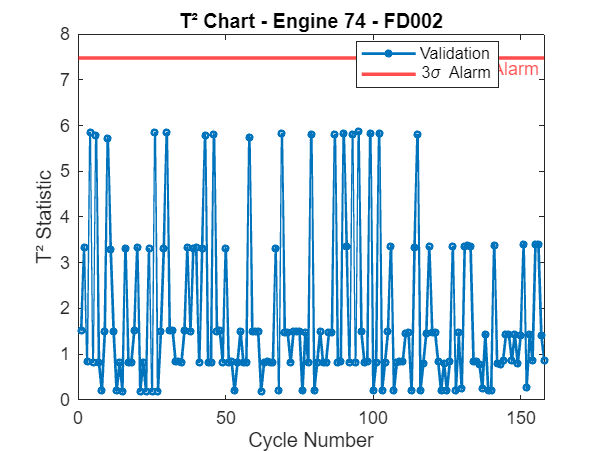

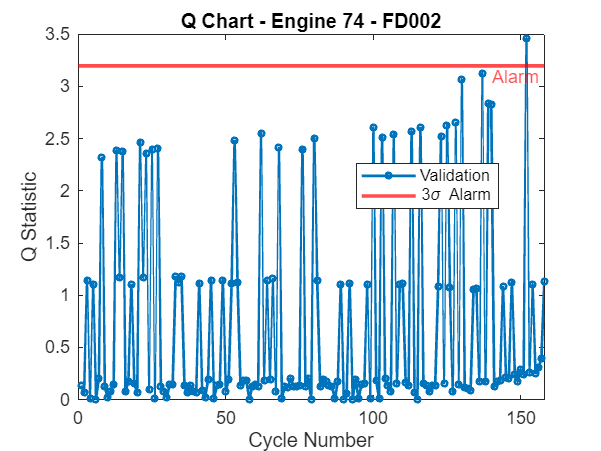


==================== Dataset: FD003 ====================


Removed 3 constant variables.


Split: 80 unit for training, 20 for validation.


Selected 11 PC to explain 90.6% of variance.


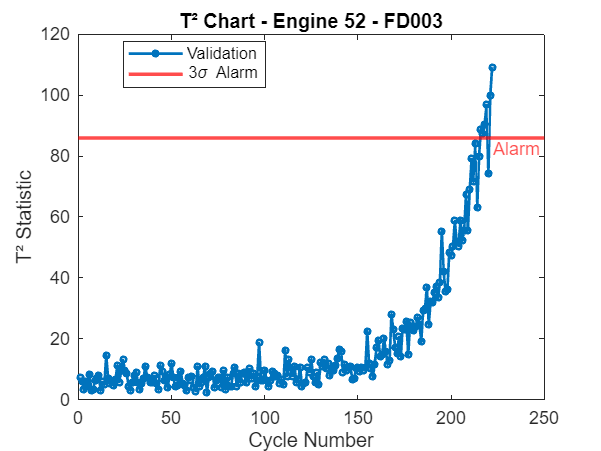

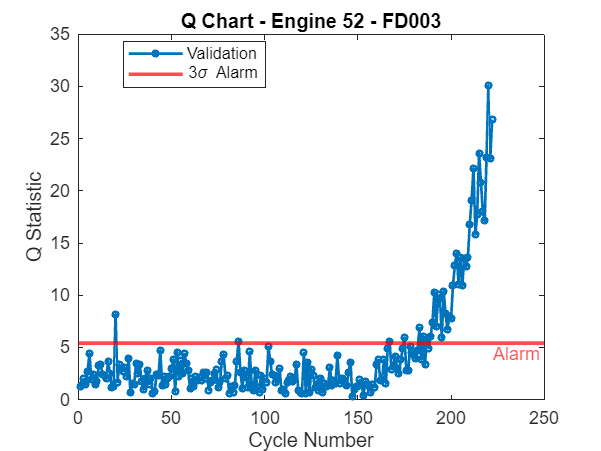

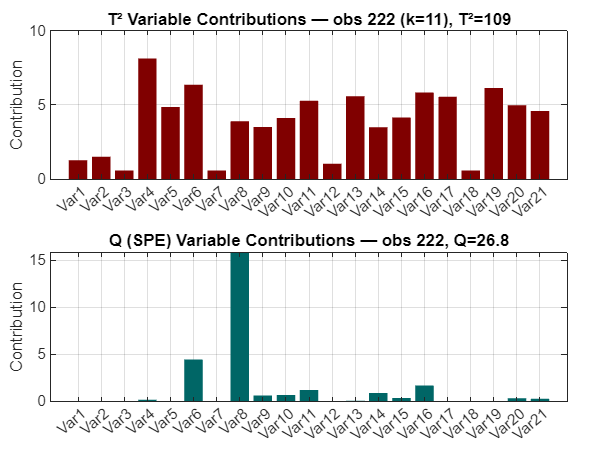

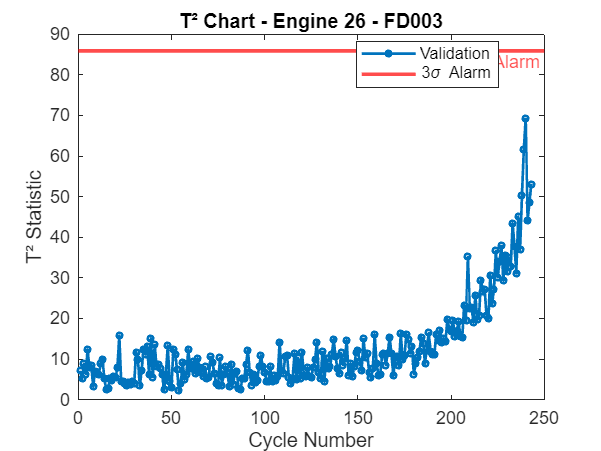

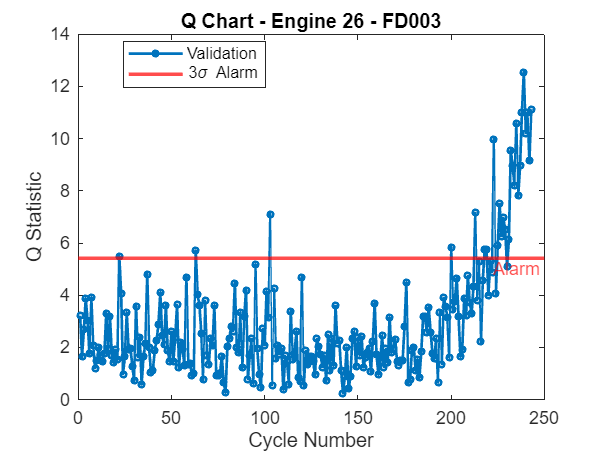

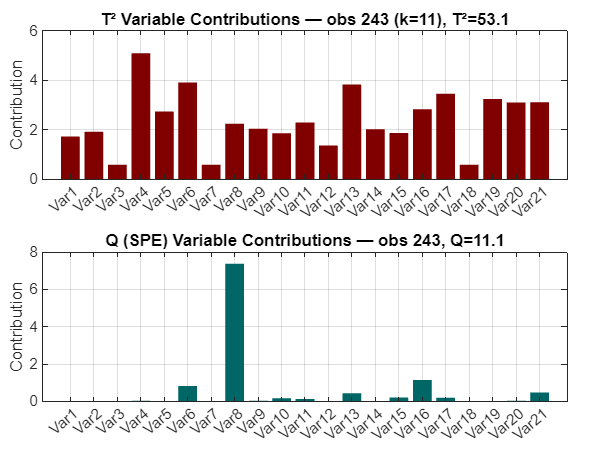

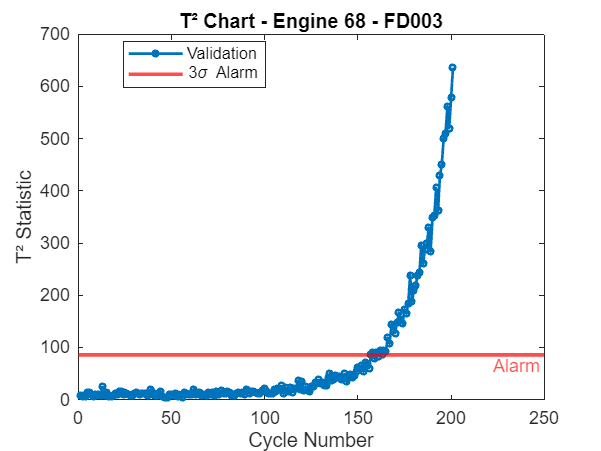

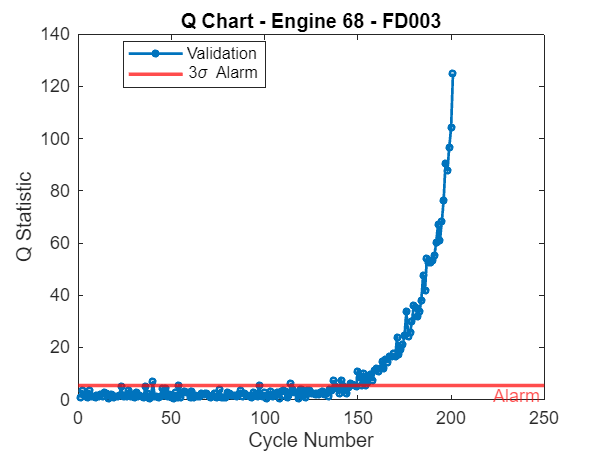


==================== Dataset: FD004 ====================


Split: 199 unit for training, 50 for validation.


Selected 2 PC to explain 97.4% of variance.


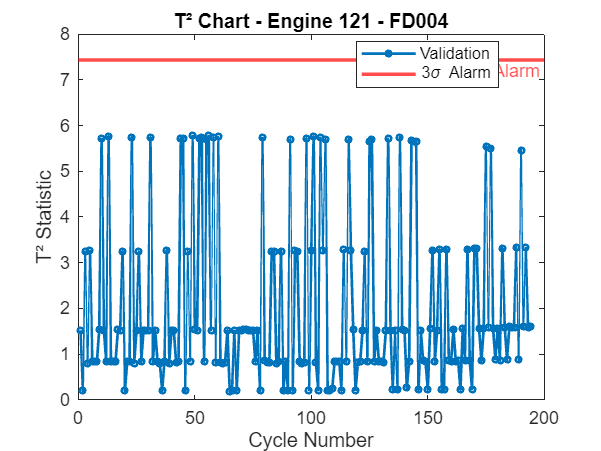

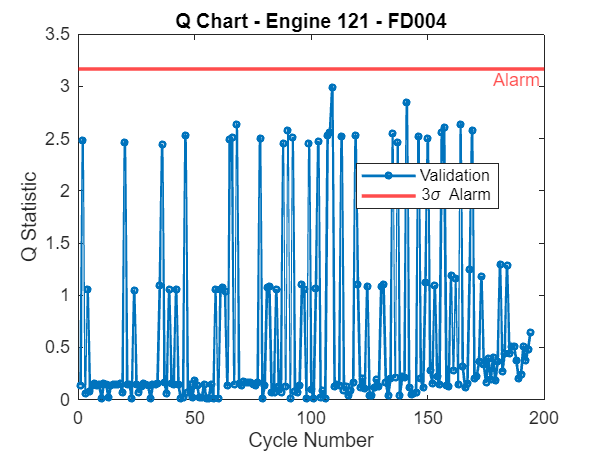

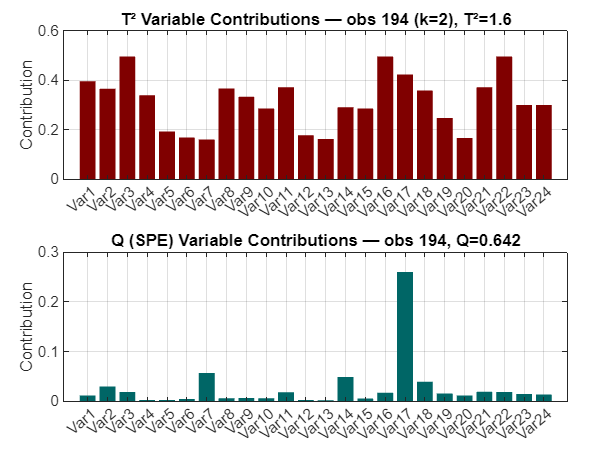

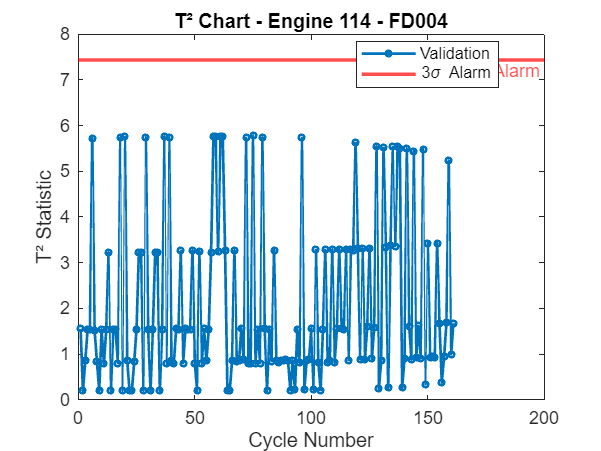

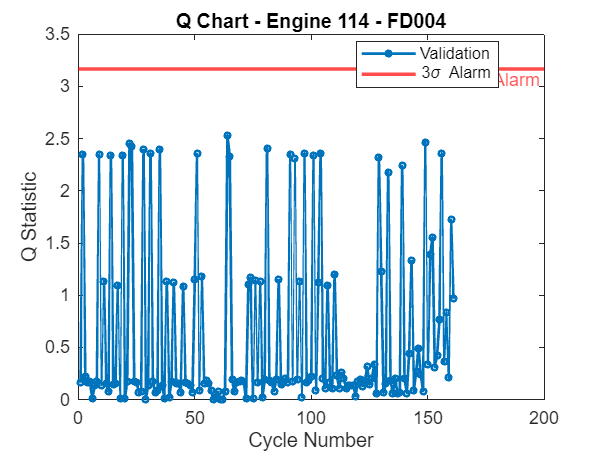

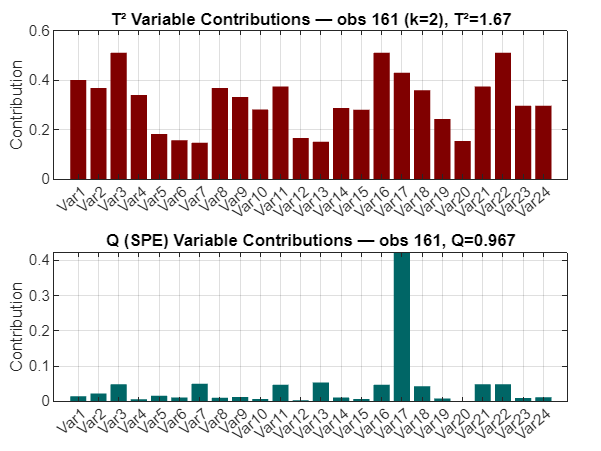

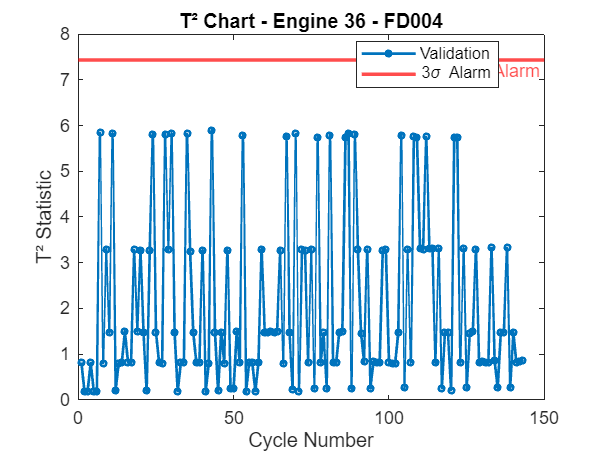

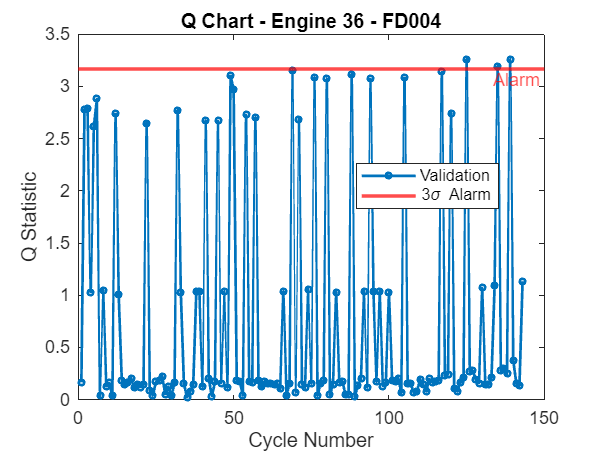

for f = 1:4
    fprintf('\n==================== Dataset: %s ====================\n', dataset_names{f});
    trainData = trainSets{f};
    testData  = testSets{f};
    RUL_true  = RULsets{f};
    unit_train  = trainData(:,1);
    cycle_train = trainData(:,2);
    X_train     = trainData(:,3:end);
    X_test_all  = testData(:,3:end);

    % Preprocessing: remove constant variables 
    varPerCol = var(X_train);
    constVars = find(varPerCol == 0);
    if ~isempty(constVars)
        fprintf('Removed %d constant variables.\n', numel(constVars));
        X_train(:,constVars) = [];
        X_test_all(:,constVars) = [];
    end
    nVar = size(X_train,2);
    varNames = arrayfun(@(x) sprintf('Var%d',x), 1:nVar, 'UniformOutput', false);

    % Split training/validation 
    uniqueUnits = unique(unit_train);
    nUnits = numel(uniqueUnits);
    rng(42); shuffled_indices = randperm(nUnits);
    split_point = floor(0.8*nUnits);
    train_unit_ids      = uniqueUnits(shuffled_indices(1:split_point));
    validation_unit_ids = uniqueUnits(shuffled_indices(split_point+1:end));
    fprintf('Split: %d unit for training, %d for validation.\n', ...
        numel(train_unit_ids), numel(validation_unit_ids));

    % Healthy Data (first 30% cycles) 
    healthy_data_indices = [];
    for i = 1:numel(train_unit_ids)
        unit_id = train_unit_ids(i);
        unit_indices = find(unit_train==unit_id);
        max_cycle = max(cycle_train(unit_indices));
        healthy_unit_indices = unit_indices(cycle_train(unit_indices) <= floor(0.30*max_cycle));
        healthy_data_indices = [healthy_data_indices; healthy_unit_indices];
    end
    X_healthy = X_train(healthy_data_indices,:);

    % PCA 
    mu = mean(X_healthy);
    sig = std(X_healthy);
    Xh_scaled = (X_healthy - mu)./sig;
    [coeff, ~, latent, ~, explained] = pca(Xh_scaled,'Centered',false);
    cumExplained = cumsum(explained);
    k = find(cumExplained>=90,1); if isempty(k), k=size(coeff,2); end
    coeff_k = coeff(:,1:k);
    latent_k = latent(1:k);
    fprintf('Selected %d PC to explain %.1f%% of variance.\n', k, cumExplained(k));

    % T² e Q
    T2_h = t2comp(Xh_scaled, coeff_k, latent_k);
    Q_h  = qcomp(Xh_scaled, coeff_k);
    alarm_T2 = mean(T2_h) + 3*std(T2_h);
    alarm_Q  = mean(Q_h)  + 3*std(Q_h);

    % Plot T² e Q for validation and test (first 3 engines validation)
    n_engines_to_plot = min(5, numel(validation_unit_ids));
    for plot_idx = 1:n_engines_to_plot
        val_id = validation_unit_ids(plot_idx);
        
        % Validation data
        indices_val = find(unit_train==val_id);
        Xv_scaled = (X_train(indices_val,:) - mu)./sig;
        T2_v = t2comp(Xv_scaled, coeff_k, latent_k);
        Q_v  = qcomp(Xv_scaled, coeff_k);
        N_val = length(T2_v);

        % Test data: match length with validation for the plot
        X_test_scaled = (X_test_all - mu)./sig;
        T2_test_all = t2comp(X_test_scaled, coeff_k, latent_k);
        Q_test_all  = qcomp(X_test_scaled, coeff_k);
        N_plot = min(N_val,length(T2_test_all));
        T2_test_plot = T2_test_all(1:N_plot);
        Q_test_plot  = Q_test_all(1:N_plot);

        % T² Chart
        figure;
        plot(1:N_val, T2_v,'-o','Color',[0,0.45,0.74],'LineWidth',1.5,'MarkerSize',3); hold on;
        yline(alarm_T2,'-r','Alarm','LineWidth',2,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','right');
        title(sprintf('T² Chart - Engine %d - %s', val_id, dataset_names{f}));
        xlabel('Cycle Number'); ylabel('T² Statistic');
        legend('Validation','3\sigma Alarm','Location','best');

        % Q Chart
        figure;
        plot(1:N_val, Q_v,'-o','Color',[0,0.45,0.74],'LineWidth',1.5,'MarkerSize',3); hold on;
        yline(alarm_Q,'-r','Alarm','LineWidth',2,'LabelVerticalAlignment','bottom','LabelHorizontalAlignment','right');
        title(sprintf('Q Chart - Engine %d - %s', val_id, dataset_names{f}));
        xlabel('Cycle Number'); ylabel('Q Statistic');
        legend('Validation','3\sigma Alarm','Location','best');

        % Plot contributes for cycle (last cycle validation)
        idxObs = N_val;
        xrow = Xv_scaled(idxObs,:);
        T2_contrib = t2contr(xrow, coeff_k, latent_k, k);
        Q_contrib  = qcontr(xrow, coeff_k, k);
        T2_val = T2_v(idxObs);
        Q_val  = Q_v(idxObs);

        figure('Color','w');
        tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

        nexttile;
        bar(T2_contrib,'FaceColor',[0.50 0 0],'EdgeColor','none');
        title(sprintf('T² Variable Contributions — obs %d (k=%d), T²=%.3g', idxObs, k, T2_val));
        ylabel('Contribution');
        xticks(1:numel(varNames)); xticklabels(varNames); xtickangle(40);
        grid on; box on;

        nexttile;
        bar(Q_contrib,'FaceColor',[0 0.40 0.40],'EdgeColor','none');
        title(sprintf('Q (SPE) Variable Contributions — obs %d, Q=%.3g', idxObs, Q_val));
        ylabel('Contribution');
        xticks(1:numel(varNames)); xticklabels(varNames); xtickangle(40);
        grid on; box on;
    end
end